**The Tabular value-fucntion methods on the cart and pole system**

Consider the cart-and-pole system here depicted:

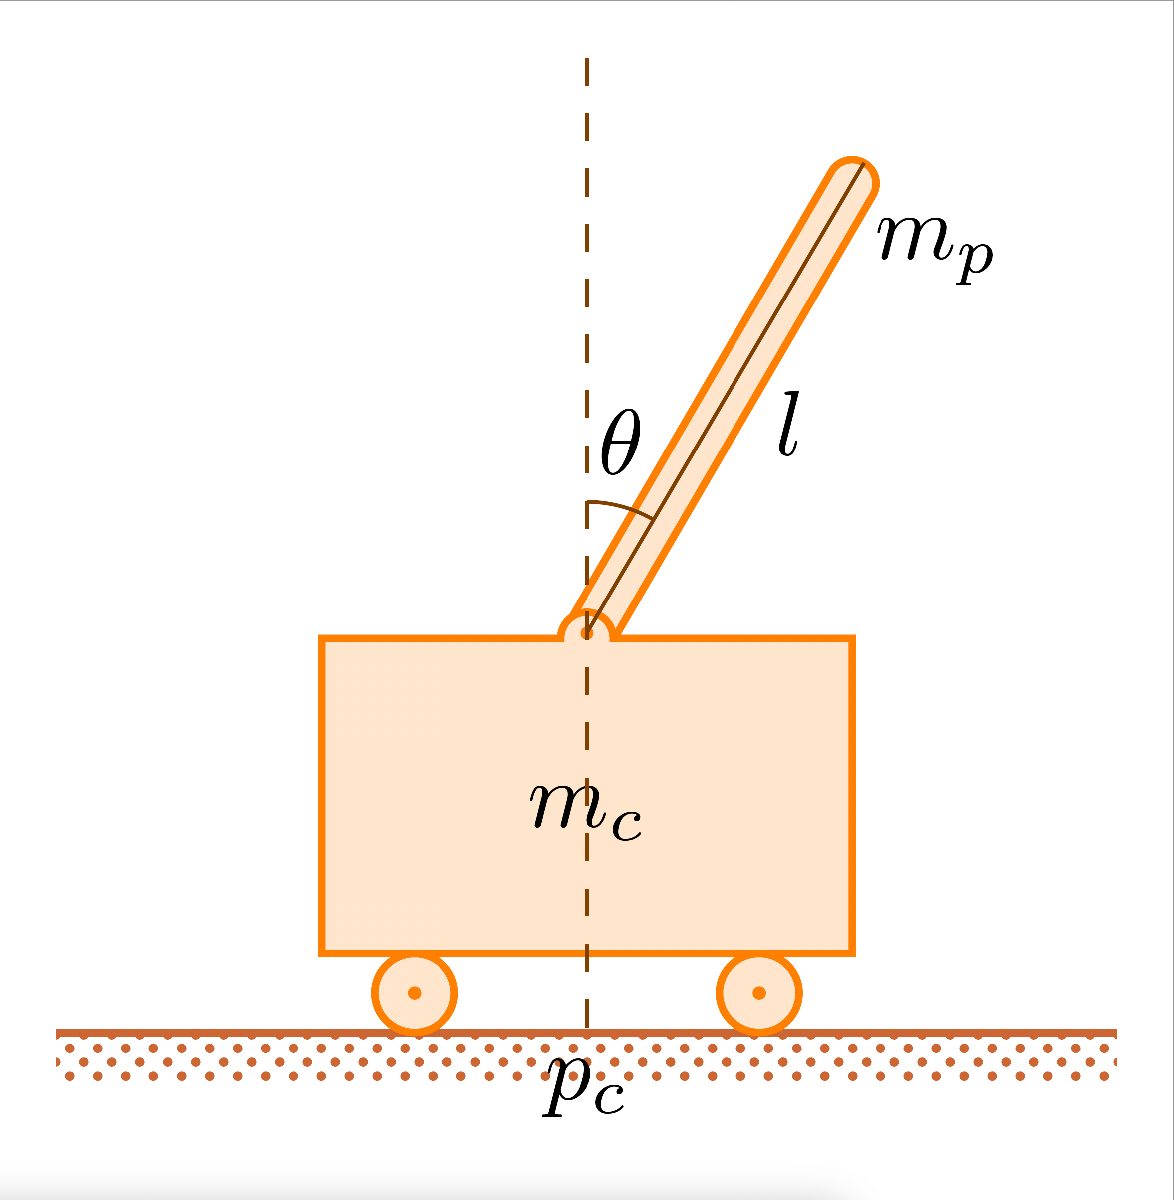

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient.

- Given the $$\mathcal{X}$$, $$\mathcal{U}$$ of the first hands-on define: the set of possible initial conditions of an episode; the terminal conditions of the episode

% Answer: (Arguing the answer)

The set of possible initial conditions is defined as

                             
$$x(0) = \left( \begin{array}{ccc}
                cp \\
                \dot cp \\
                \theta \\
                \dot \theta
\end{array} \right)
=
 \left( \begin{array}{ccc}
                \{-3, +3\} \ m \\
                 \{-3, +3\} \ m/sec\\
                \{-\pi/6,+\pi/6 \}\ rad \\
                \{-3, +3\} \ rad/sec
\end{array} \right);$$


                             
$$u(0) = 0 \ N;
$$


and the terminal episodes are:

- if the pole is going to fall, $\theta = \{-\pi/4,\ +\pi/4 \} \ rad
$ or the cart position is going out of the constraints $cp = \{ -5, +5\}\ m;$

- if the control input overcome the limit force $u = \{-10, +10\} \ N$

- if the episode (500 steps when the system will be discretized) overcome the limit of $10 \sec$ and $\theta = \{-0.10, \ +0.10\} \ rad$ wich are equal to $\theta = \{-9, +9\}\ deg$

        2. Provide a proper discretization of the state space $$\mathcal{X}$$, and define the size of the action-value function $Q$

% Answer: (Arguing the answer)

% ricorda di inserire un valore inutilmente grande per quando lo stato va
% fuori dai limiti imposti
% se il carrello va fuori dai 6 metri può essere tutto riconducibile ad
% essere arriavto a 100 metri, tamto mi serve solo per il calcolo dell Q
% dato che gli serve lo stato discretizzato anche all'istante k+1

The cart position has one level of dicretization of 1200 step in 6 total meter in which the cart wil be able to move, that correspond to a 1 cm step.

If the cart position will exeed the constraints, the value will be discretized at 60 m

The cart speed will has 3 level of dicretizadion:

- The first from [-3, -2) and (+2, +3] m/s of a step of 0.25 m/s (8 total steps)

- The second from [-2, -1) and (+1, +2] m/s of a step of 0.1 m/s (20 total steps)

- The last one from [-1, +1] m/s of a step of 0.05 m/s (40 total steps)

- If the cart speed will exeed the constraints, the value will be discretized at 30 m/s

The angular position will has 5 level of discretization:

- The first from [-45, -30) and (+30, +45] deg of a step of 1.5 deg (15 total steps)

- The second from [-30, -20) and (+20, +30] deg of a step of 1 deg (20 total steps)

- The  third from [-20, -15) and (+15, 20] deg of a step of 0.5 deg ( 20 total steps)

- The fourth from [-15, -9)  and  (+9, +15] deg of a step of 0.1 deg ( 120 total steps)

- The last one from [-9, +9]deg of a step of 0.05 deg ( 360 total steps) 

- If the angular position will exeed the constraints, the value will be dicretized at $\pi
$

The angular speed will has 4 level of discretization 3, 2, 1, 0.5  TO BE FINISHED

- The first from [-3, -2) and (+2, +3] rad/s of a step of 0.5 rad/s (4 total steps)

- The second from [-2, -1) and (+1, +2] ard/s of a step of 0.25 rad/s (8 total steps)

- The third one from [-1, -0.5) and (+0.5, +1] rad/s of a step of 0.1 rad/s (10 total steps)

- The last one from [-0.5, 0.5] rad/s of a step of 0.05 (20 total steps)

- if the angular speed will exeed the constraints, the value will be discretized at 30 rad/s

The size of the cation-value function Q wil be $|pc| * |\dot pc| * |\theta| * |\dot \theta|$

        3. Create a code able to select the discretized version of a measured state $x$

% Provide the code
pc = [-60, -6:0.5:6, 60]'; % oppure la tolgo, tanto non me ne frega niente della sua posizione
pc_dot = [-30, -3:0.5:-2, -1.9:0.25:-1.1, -1:0.1:+1, 1.1:0.25:1.9, 2:0.5:3, 30]'; % anche di questa mi importa poco, basta che non vada fuori dai "limiti fisici" della realtà
theta = [-180, -30:3:-21, -20:1:-15.5, -15:0.5:-9.1, -9:0.25:9, 9.1:0.5:15, 15.5:1:20, 21:3:30, 180]'; % questo direi che è particolarmente importante
theta_dot = [-30, -3:0.75:-2.5, -2:0.5:-1.25, -1:0.25:-0.6, -0.5:0.1:0.5, 0.6:0.25:1, 1.25:0.5:2, 2.5:0.75:3, 30]'; % questo altrettanto, ma non troppo, è solo una conseguenza del mio controllo, anche questo non deve uscire dai limiti fisici della realtà

Q_table = zeros(2, 27, 37, 117, 23); % the first index is for the control input equal to -10 or 10 N;

% check if the state is out of the constraints

% remember to convert rad to degree

if(curr_state(1) < (-6) || curr_state(1) > 6)
    %stop episode
end

if(curr_state(2) < (-3) || curr_state(2) > 3 )
    %stop episode
end

if(curr_state(3) < (-45) || curr_state(3) > 45 )
    %stop episode
end

if(curr_state(4) < (-3) || curr_state(4) > 3 )
    %stop episode
end

% find the index corresponding to the clossesti discretization for the
% current state

pc_index = knnsearch(pc, curr_state(1));
pc_dot_index = knnsearch(pc_dot, curr_state(2));
theta_index = knnsearch(theta, curr_state(3));
theta_dot_index = knnsearch(theta_dot, curr_state(4));

4. Given the terminal conditions of the episode (selected in 1.) create a code able to perform a fixed number of episodes of a fixed number of steps, starting from random initial conditions and applying random inputs.

% Provide the code

init_cond = zeros(1,4);
init_cond(1) = rand; % from -3 to +3
init_cond(2) = rand; % from -3 to +3
init_cond(3) = rand; % from -30 to + 30 degree
init_cond(4) = rand; % from -3 to +3 rad/s

% RICORDA DI VEDERE PRIMA CON UN SOLO EPISODIO

% posso fare da 10^3 a 10^5 episodi, qualche min per eseguire
% NB Reward definito come norma del vettore stato(i) preso in considerazione

      5. Create a function able to perform $$\epsilon$$-greedy policy for a chosen $$\epsilon$$.

% Provide the code

      6. Create a code that applies Tabular Q-Learning algorithm.

% Provide the code

      7. Copy and paste your Q-learning algorithm and apply the changes needed to convert it into a SARSA algorithm

% Provide the code